Круглый цилиндр, H-поляризация

По методу из гибсона для сравнения.

21_10_20

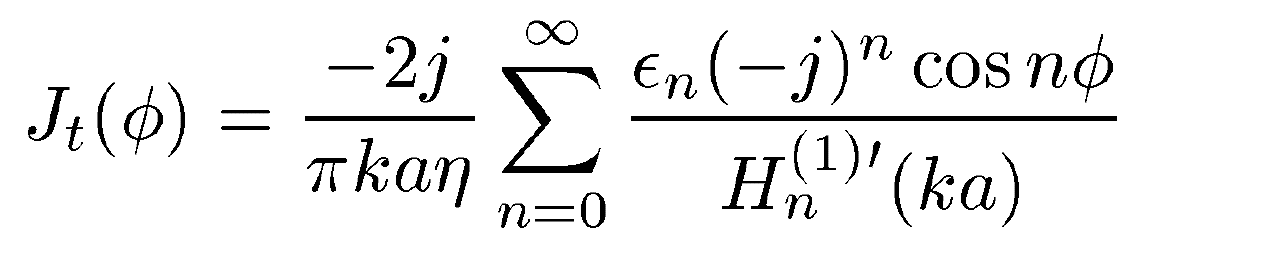

Гибсон стр 115

close all;
clear variables;

f01 = fopen('I_Gibson_method.dat','w');

% исходные данные
R = 2;
N = 600;
n_harmonic = 250; % кол-во гармоник

% константы
eta = 120*pi;
k = 2*pi; 


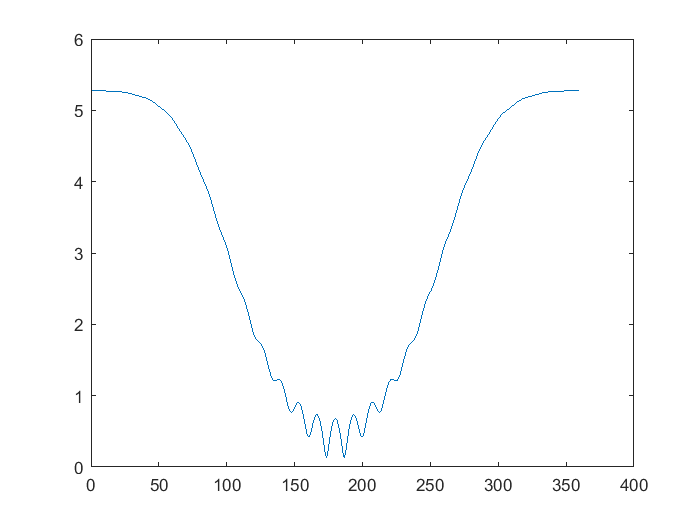

% генерация углов и списка углов
delta_phi = 360/N;
for i = 1 : N 
    phi_list(i) = delta_phi*i; % список углов
end

% кол-во точек
for n_dot = 1 : N
    
    % текужщий угол
    current_phi = phi_list(n_dot);
      
    % кол-во гармоник
    Sum = 0;
    for n = 1 : n_harmonic
        if (n-1) == 0
            epsilon = 1;
        else
            epsilon = 2;
        end

        H_der = (n-1)/(k*R)*besselh((n-1),1, k*R)-besselh((n), 1, k*R); % производная функции
        Sum = Sum + epsilon*(-1i)^(n-1)*cosd((n-1)*current_phi)/H_der;        
    end
    
    I(n_dot) = (-2*1i)/(pi*k*R*eta)*Sum;
end

% в соотвествии с литературой умножим на 1000
ImA = abs(I)*1000;

plot(phi_list, ImA)

Запись в файл

for n=1:N
    Inorm = abs(I)*1000;
    fprintf(f01,' %10.5f %10.5f\n', phi_list(n), Inorm(n));
end

fclose(f01);